# von Karman beam with 1:3 internal resonance

In this example, we consider a clamped-pinned von Karman beam with a support spring at its midspan. The stiffness of the support spring is tund such that 1:3 internal resonance occurs between the first two bending modes. We then extract the forced response curve using SSM reduction. 

clear all

## Model Setup

Building FE model


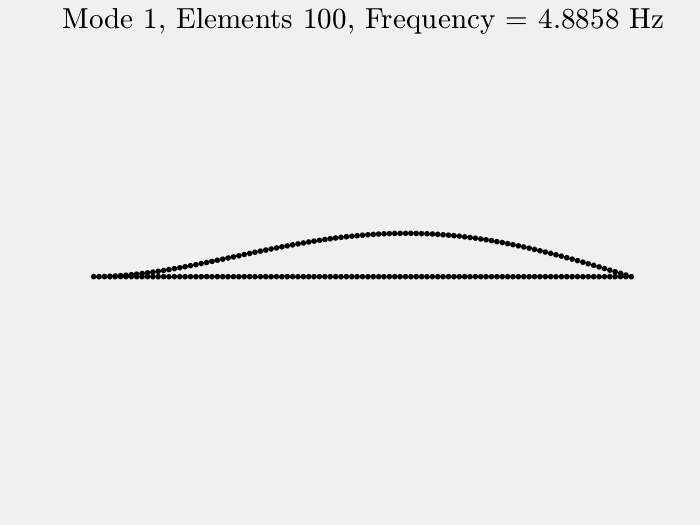

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
Getting nonlinearity coefficients
Assembling Tensors
Assembling external force vector


nElements = 100;
[M,~,K,fnl,~,Outdof] = build_model(nElements);

outdof = Outdof(2); % the point at mid span
n = length(M);
Kc = K;

The beam is discretized with 100 elements and then 298 degrees-of-freedom. The dimension of phase space of the full system is 596. With the SSM reduction, the dimension of phase space will be reduced to four. Numerical experiments show that 1:3 near resonance is observed when the stiffness of the support spring is around 37. Next we set the stiffness to be 37 and then perform SSM reduction.

## Dynamical System Setup

kLinear = 37;
Kc(outdof,outdof) = K(outdof,outdof)+kLinear;   % linear part
kNonlinear = 0;                                 % nonlinear part
f3_new  = fnl{2};
fnl_new = fnl;
f3_new(outdof,outdof,outdof,outdof) = f3_new(outdof,outdof,outdof,outdof)+kNonlinear; % cubic nonlinerity
fnl_new{2} = f3_new;
C = (2e-4)/9*Kc;

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',Kc,'fnl',fnl_new);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex');

## Primiary resonance with IRs

**Add forcing -  a concentric harmonic force is applied at the midspan**

f_0 = zeros(n,1);
f_0(outdof) = 1000;
kappas = [-1; 1];
epsilon   = 0.02;
coeffs = epsilon * [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas);

**Create SSM**

S = SSM(DS);
set(S.Options, 'reltol', 0.8,'notation','multiindex')

**Extract FRC**

Here we use the extract_FRC routine to obtain the forced response curve over $[0.96,1.05]\omega_1$.

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.688485e-04
modal damping ratio for 2 mode is 1.106767e-03
modal damping ratio for 3 mode is 2.309722e-03
modal damping ratio for 4 mode is 3.944138e-03
modal damping ratio for 5 mode is 6.019377e-03

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0001 + 0.3320i
  -0.0001 - 0.3320i
  -0.0011 + 0.9961i
  -0.0011 - 0.9961i
  -0.0048 + 2.0787i
  -0.0048 - 2.0787i
  -0.0140 + 3.5497i
  -0.0140 - 3.5497i
  -0.0326 + 5.4173i
  -0.0326 - 5.4173i

The master subspace has internal resonances: [1  1  3  3]
*****************************************
Calculating FRC using SSM with master subspace: [1  2  3  4]
(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     

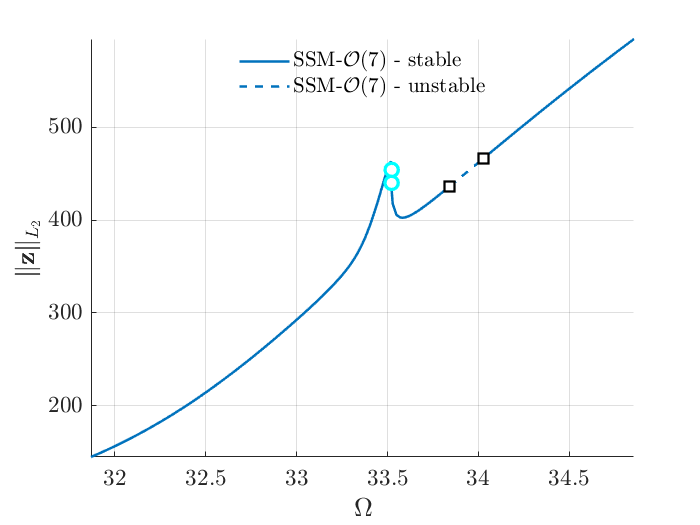

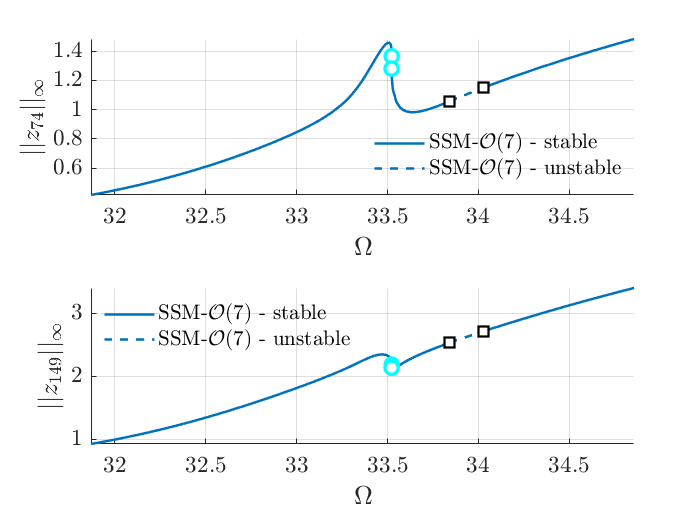

Total time spent on FRC computation upto O(7) = 00:00:28


om = eigs(Kc,M,2,'smallestabs');
om = sqrt(om);
freqRange = [0.96 1.05]*om(1);
order = 7;
set(S.FRCOptions, 'nCycle',50000);
set(S.FRCOptions, 'initialSolver','forward');
set(S.contOptions, 'h_max', 0.2, 'PtMX', 1000, 'ItMX',20);
set(S.FRCOptions, 'omegaSampStyle','cocoBD');
set(S.FRCOptions, 'method','continuation ep','outdof',Outdof');
FRC = S.extract_FRC('freq', freqRange, order);

As an alternative, we can use SSM-ep toolbox to obtain the curve.

(near) outer resonance detected for the following combination of master eigenvalues
     0     0     2     0
     1     0     2     0
     0     0     3     1
     1     1     2     0
     3     0     1     0
     0     2     3     0
     1     0     3     1
     2     1     2     0
     4     0     1     0
     0     0     4     2
     0     3     3     0
     1     1     3     1
     2     2     2     0
     3     0     2     1
     4     1     1     0
     6     0     0     0
     0     2     4     1
     1     0     4     2
     1     3     3     0
     2     1     3     1
     3     2     2     0
     4     0     2     1
     5     1     1     0
     7     0     0     0
     0     0     5     3
     0     3     4     1
     1     1     4     2
     1     4     3     0
     2     2     3     1
     3     0     3     2
     3     3     2     0
     4     1     2     1
     5     2     1     0
     6     0     1     1
     7     1     0     0
     0     2     5     2
     0     5    

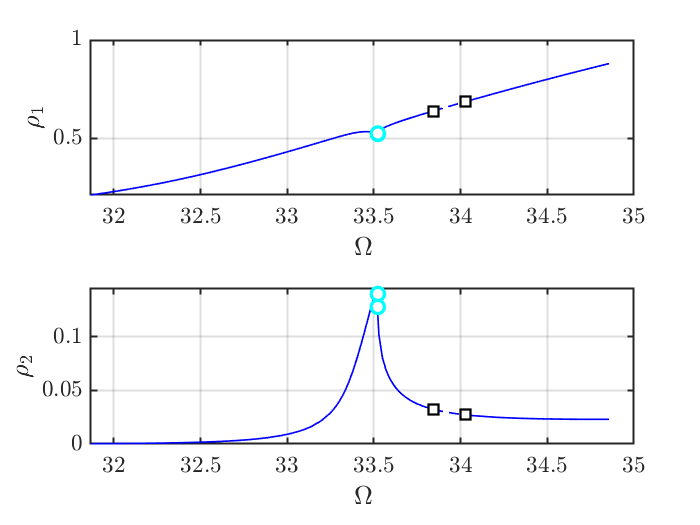

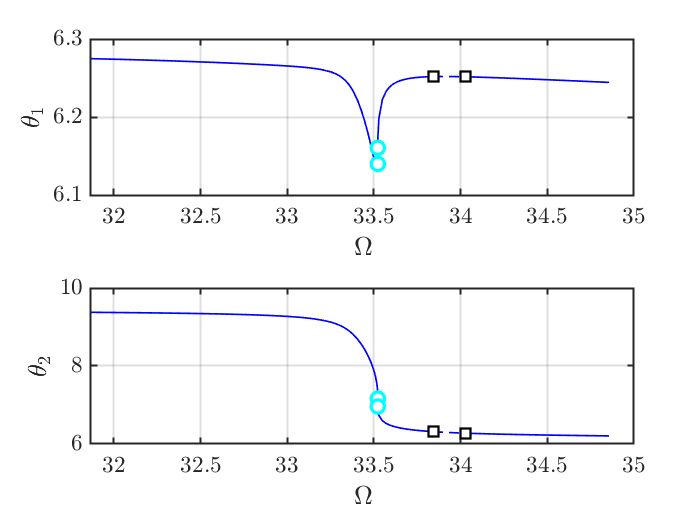

the forcing frequency 3.1869e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.1899e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.1957e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2018e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2075e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2134e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2191e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2250e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2306e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequency 3.2366e+01 is nearly resonant with the eigenvalue -1.2244e-02 + i3.3196e+01
the forcing frequenc

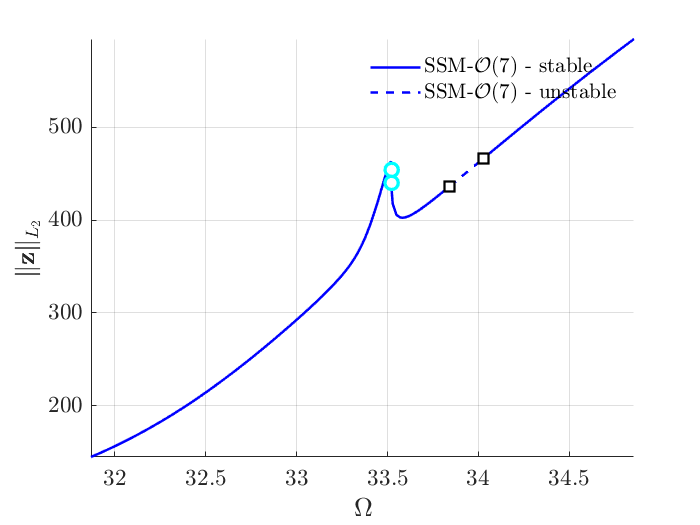

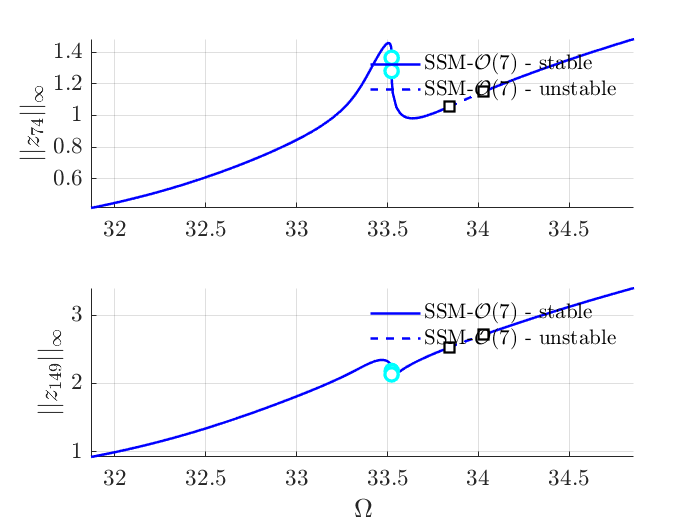

S.SSM_isol2ep('isol',[1 2 3 4],order,[1 3],'freq',freqRange,Outdof);

**Exercises**

- Use SSM_isol2ep to calculate the forced response curve with varied forcing amplitude $\epsilon$.

- Use SSM_ep2SN to locate the solution manifold of saddle-node bifurcation periodic orbits.

- Use SSM_ep2HB to locate the solution manifold of torus bifurcation periodic orbits.